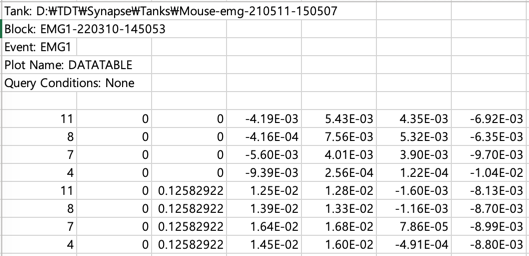

reader = channelReader();

tic 
%                            
reader.readMultiChannelFile( ...
    "./data/height1 - 1,10s - 2x.xlsx", ...#filename
    1, ...#channelColumnIdx
    3, ...#timeColumnIdx
    7, ...#startRowIdx
    4, ...#startColIdx
    nan ... #sample frequency. time column이 있으면 자동으로 frequency 계산하므로 nan을 입력
    ); %일단 파일을 불러옴

This file has 4 channels: 

ans =      4     7     8    11


toc % 코드 실행 시간 측정. 오래 걸림.

경과 시간은 3.494913초입니다.


%                            organoid, channel, month 


#### 1. 특정 시간 구간의 signal만 사용하기

emg = reader.readSingleChannelFromFile(1, 8, 1);

sampling rate = 1017.252602Hz
starts at 0.000000, ends at 54.859530, duration = 54.859530
number of timestamps = 55807

(optional)

20-200hz 구간만 남기고 지움(Classification of Five Finger Movement, based on a Low-cost, Real-time EMG System)

emg.bandPass([20,200])


emg.cutTime([10,20]);

new startTime = 9.999483
new endTime = 20.000932
new duration = 10.001449
new nTimestamp = 10175


fgfgfg

fgfg

emg.rectify();

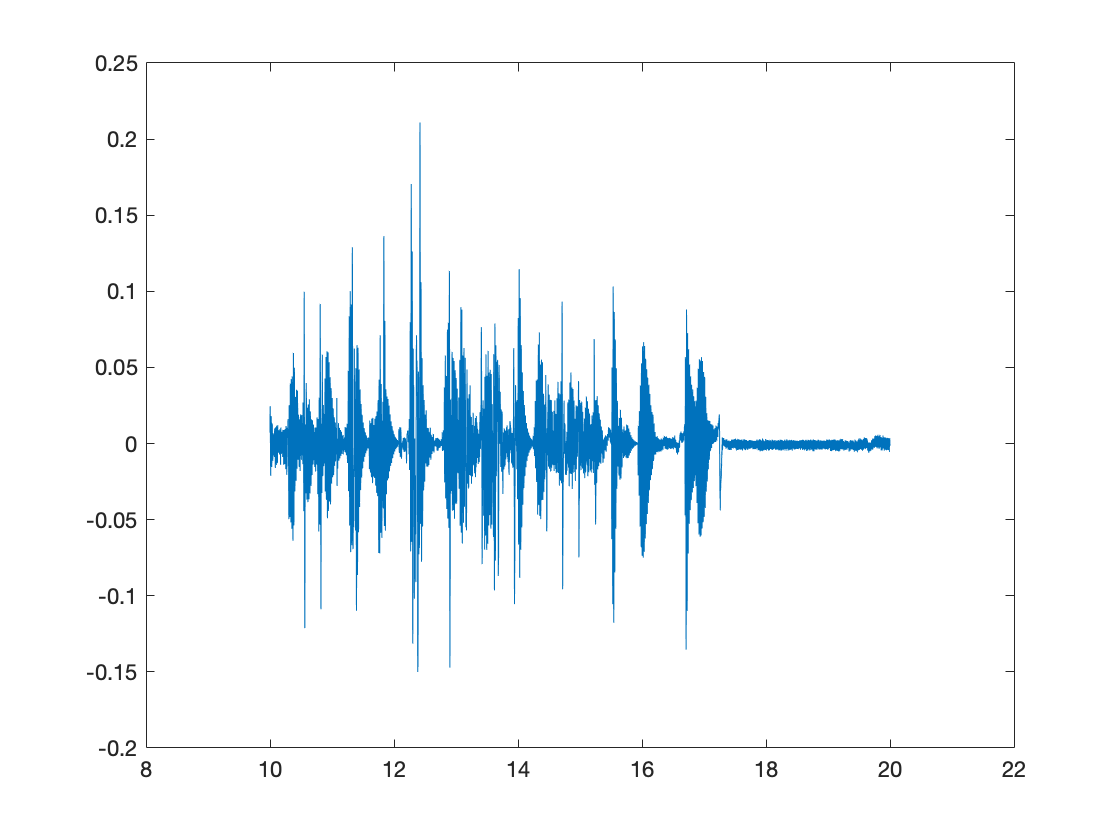

plot(emg.t, emg.raw)

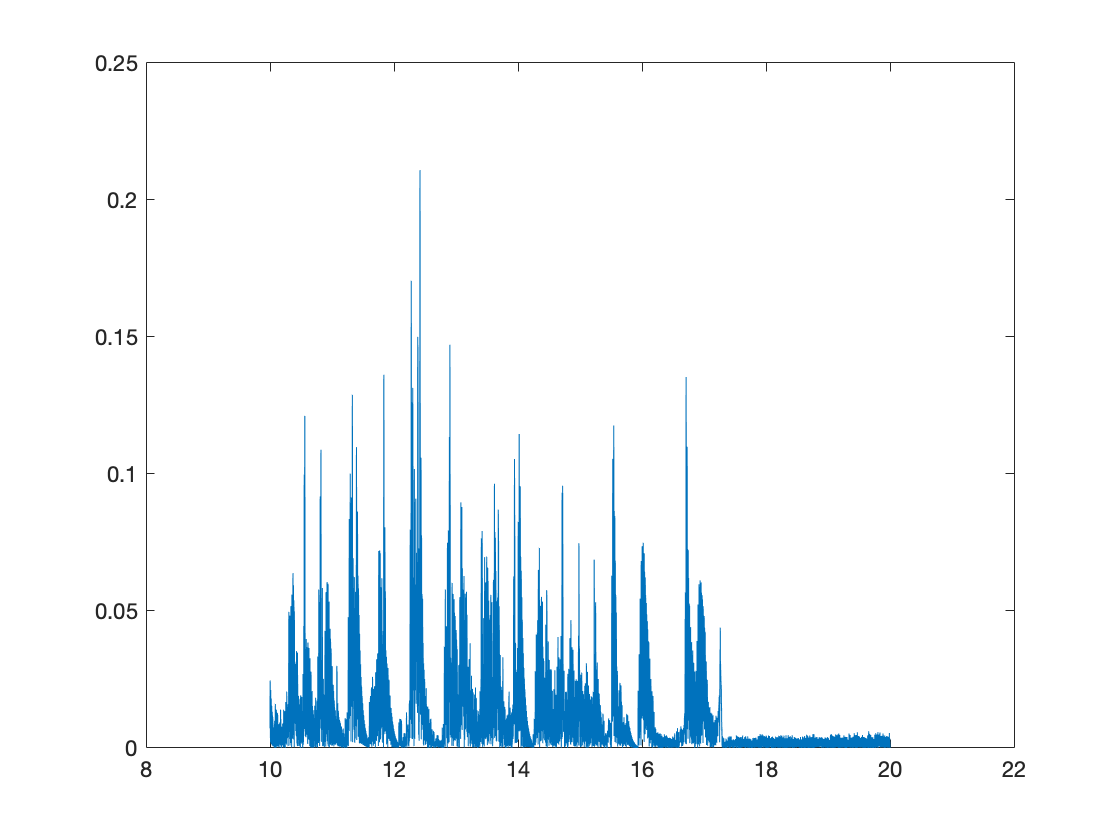

plot(emg.t, emg.signalRawRectified)

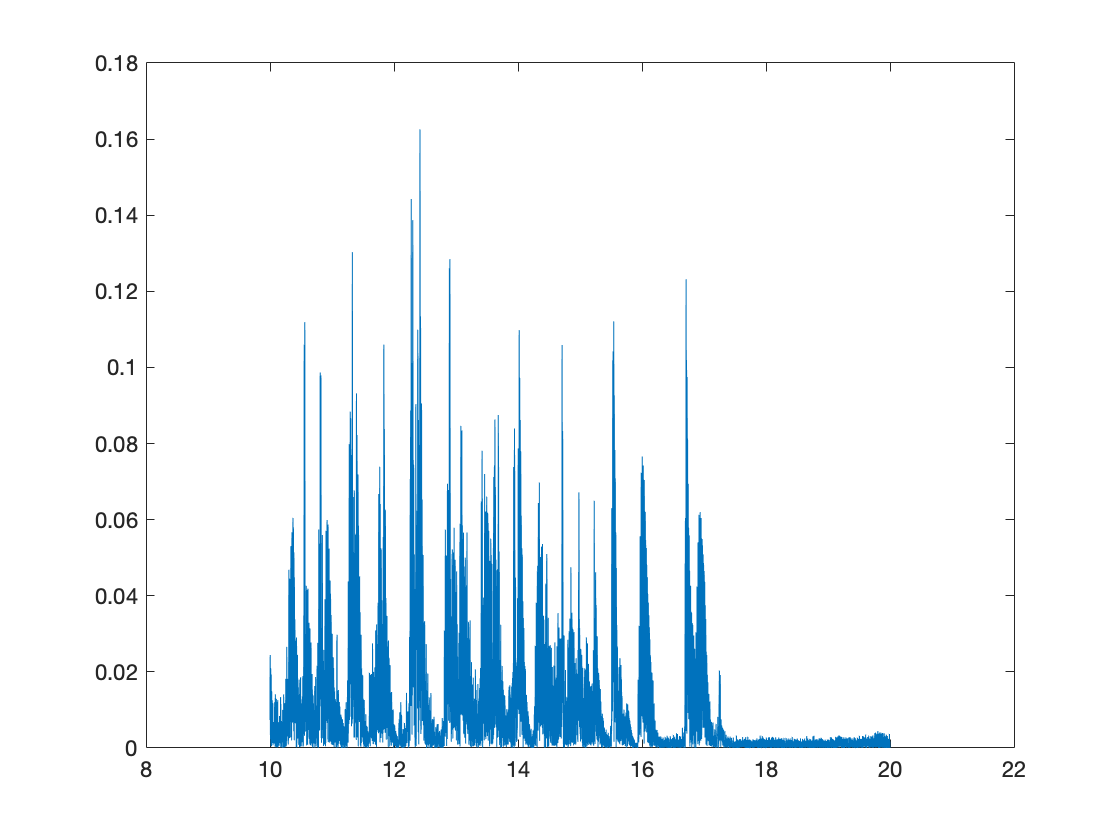

plot(emg.t, emg.signalFilteredRectified)

dfdf

matlab signal processing toolbox 설치 필요

Computes the RMS-envelope, the MA-envelope ot the LE-envelope of an EMG signal.

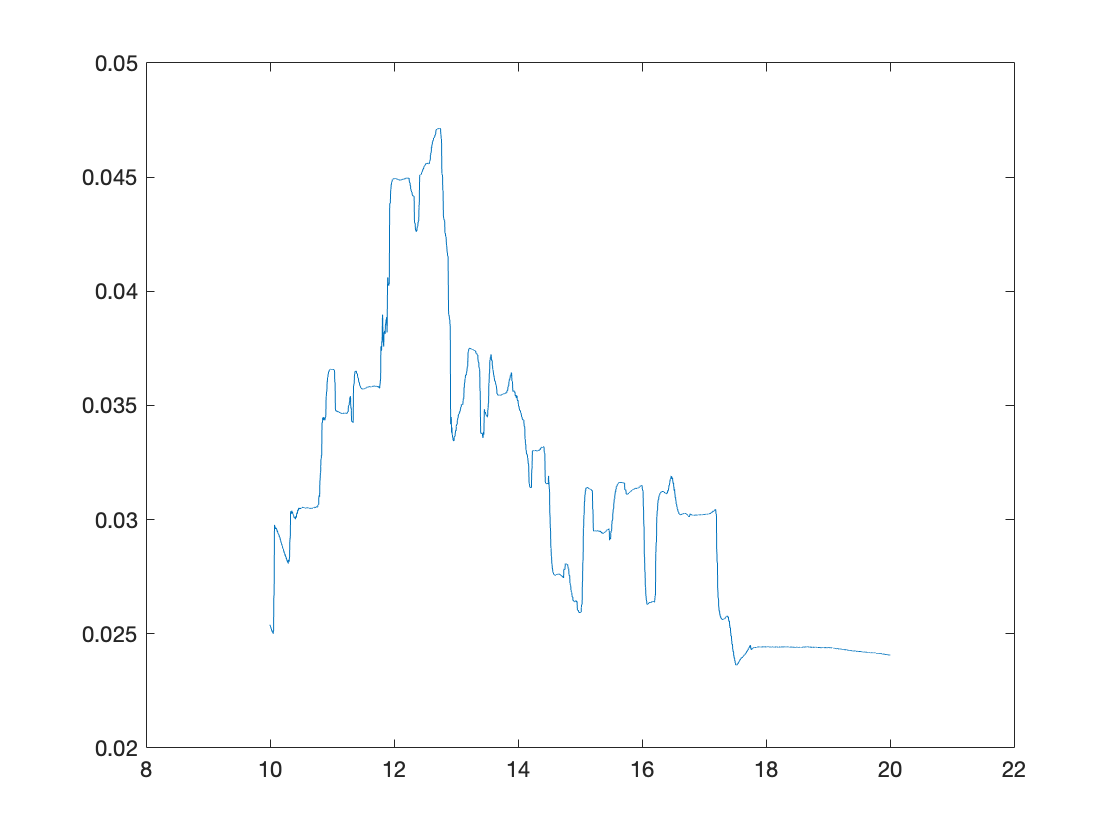

emg.envelope(1000);
plot(emg.t, emg.signalRawEnveloped)

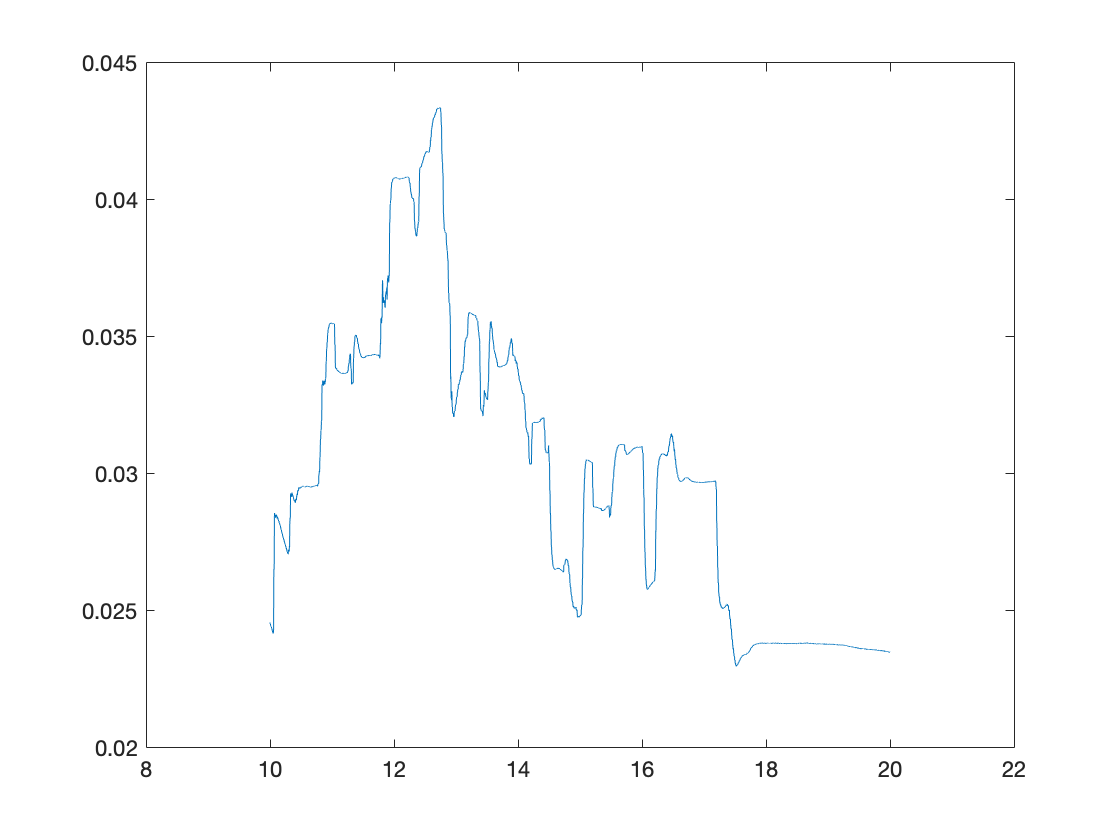

plot(emg.t, emg.signalFilteredEnveloped)

dfdf

length(emg.signalFilteredEnveloped)

ans = 10175

ㅓㅏ

ㅓ

ㅓ

%                                 organoid, month
pixels = reader.readManyChannelsFromFile(1, 1)

이 연산에 대해 배열 크기가 호환되지 않습니다.

오류 발생: channelReader/readSingleChannelFromFile (87번 라인)
            channelBoolean = chReader.massiveDataChannelRows == channelNum; %channel num에 해당하는 row만 골라냄 

오류 발생: channelReader/readManyChannelsFromFile (113번 라인)
                channelObjects{channelNum} = chReader.readSingleChannelFromFile(organoidNum, channelNum, month);

<